rho = 2;
p = 300

p = 300

Delta = 4

Delta = 4

%path_result = '/mnt/nas/users/user213/sparse_kmeans/experiment/13_02_09_2024/AR1/result/rho2_Delta4_p800.csv'

%p=
%Delta=
%rho = 
rho = rho /10

rho = 0.2000

%addpath(genpath('/mnt/nas/users/user213/sparse_kmeans'))
feature("numcores")

MATLAB detected: 10 physical cores.
MATLAB detected: 10 logical cores.
MATLAB was assigned: 10 logical cores by the OS.
MATLAB is using: 10 logical cores.


ans = 10

maxNumCompThreads(2);




s = 10;
n_rep = 1;


n=500;
K=2;
rounding = 1e-4;
cluster_true = [repelem(1,n/2), repelem(-1,n/2)];
n_iter = 5; 



clustering_acc_mat = repelem(0, n_rep );






Omega = zeros([p,p]);
        for j=1:p
            for l = 1:p
                if j==l
                    Omega(j,l) = 1;
                elseif abs(j-l) ==1
                    Omega(j,l) = rho;
                end
            end
        end


Sigma = inv(Omega);
M = Delta/2/ sqrt( sum( Sigma(1:s,1:s),"all") )

M = 0.7341

sparse_mean = [repelem(1,s), repelem(0,p-s)]'; %column vector
mu_0_tilde =  M * sparse_mean;
mu_0 = Sigma*mu_0_tilde;
mu_1 = -mu_0;
mu_2 = mu_0;

beta = linsolve(Sigma, (mu_1-mu_2));
fprintf( "delta confirmed: %f", sqrt( (mu_1-mu_2)' * beta ))

delta confirmed: 4.000000

norm((mu_1-mu_2))

ans = 3.4740

tic

mu_1_mat = repmat(mu_1,  1, n/2); %each column is one observation
mu_2_mat = repmat(mu_2, 1, n/2);%each column is one observation
x_noiseless = [ mu_1_mat  mu_2_mat ];%each column is one observation 
x_noisy = x_noiseless +  mvnrnd(zeros(p,1), Sigma, n)';
x_noisy_half = x_noisy(:,1:n/2);
sample_cov =  cov(x_noisy_half')

sample_cov =     1.1871   -0.2873    0.1425    0.0430   -0.0345    0.0742   -0.0612   -0.0062   -0.0088   -0.0087   -0.0115    0.0023   -0.0351    0.0851   -0.0437   -0.0960    0.0355    0.0069    0.0105   -0.0425    0.0763   -0.1861    0.1266   -0.0406   -0.0351    0.0329   -0.0005   -0.0445    0.0402    0.0306    0.0818    0.1204   -0.0278   -0.0429    0.0023   -0.0502    0.0683   -0.0147    0.0426    0.0110    0.0791   -0.0311   -0.1230    0.0558    0.0043    0.1508   -0.0477   -0.0443   -0.1008    0.0545
   -0.2873    1.2033   -0.4394    0.1411   -0.1209    0.0365   -0.0607    0.0042   -0.0685   -0.0271   -0.0175   -0.1462    0.0650   -0.0057   -0.0574    0.0172    0.0211   -0.0720   -0.0413   -0.0111   -0.0336    0.0570   -0.1107    0.0308   -0.0859   -0.0141    0.0974    0.0809    0.0507   -0.0505    0.0650    0.0057    0.1048   -0.0482   -0.0390   -0.0898    0.0699   -0.0978    0.0654   -0.0109    0.1213   -0.0161    0.1843   -0.0108   -0.0402   -0.0588    0.0376   -0.1249    0.

iteration: (1)th 



init_method = 'hc'

sdp_method = 'basic'


p = 10, acc_init: 0.942000 
n_{G1}_init = 251, n_{G1}_init = 249
threshold: (2.145966)

1 th thresholding



lambda_sort =   140.6185  153.1326  157.2694  164.2522


lambda_sort_index =      2     3     1     4


ans = 4.0322e-06

top_10 =    45.7376
   43.9346
   35.5641
   34.0590
   33.8598
   33.7705
   31.5671
   31.4670
   28.2328
   24.1643


top_10_idx =      1
    10
     8
     5
     6
     4
     9
     3
     2
     7


kmeans_sdp is not found in the current folder or on the MATLAB path, but exists in:
    /Users/jmmoon/Documents/GitHub/sparse_kmeans/SDPNAL+v1.0

Change the MATLAB current folder or add its folder to the MATLAB path.

Error in iterative_kmeans_spectral_init_glasso (line 1

sample_cov =     1.0726   -0.2403    0.0906   -0.0174   -0.0350   -0.0859    0.1432    0.0023    0.1489    0.0999
   -0.2403    1.0316   -0.1891    0.0640   -0.0927    0.1108   -0.1123    0.0510   -0.0841    0.0072
    0.0906   -0.1891    1.1653   -0.1661    0.0402   -0.0688   -0.0472   -0.0161   -0.0256    0.0026
   -0.0174    0.0640   -0.1661    1.0453   -0.0326   -0.0116    0.0663   -0.0252   -0.0115   -0.0980
   -0.0350   -0.0927    0.0402   -0.0326    0.9534   -0.1029    0.0648    0.1037   -0.0217    0.0184
   -0.0859    0.1108   -0.0688   -0.0116   -0.1029    1.0105   -0.2309    0.0250   -0.0095    0.0469
    0.1432   -0.1123   -0.0472    0.0663    0.0648   -0.2309    1.0148   -0.1352    0.0459   -0.0271
    0.0023    0.0510   -0.0161   -0.0252    0.1037    0.0250   -0.1352    0.9481   -0.1747    0.0411
    0.1489   -0.0841   -0.0256   -0.0115   -0.0217   -0.0095    0.0459   -0.1747    0.9475   -0.1648
    0.0999    0.0072    0.0026   -0.0980    0.0184    0.0469   -0.0271    0.04

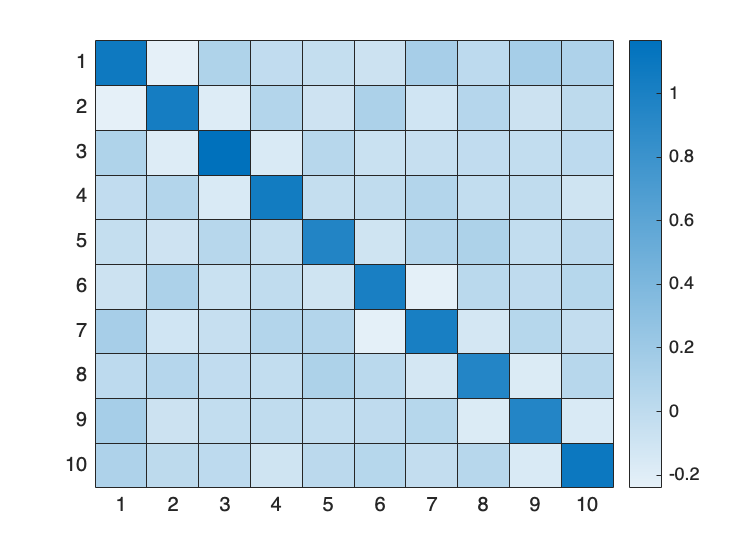


Omega_est_now= L1precisionBCD(sample_cov, 0.1)

Iter = 1, OptCond = 1474.96131
Column = 1, OptCond = 1474.96131
Column = 2, OptCond = 1462.86957
Column = 3, OptCond = 1450.18435
Column = 4, OptCond = 1438.99106
Column = 5, OptCond = 1427.55754
Column = 6, OptCond = 1414.90996
Column = 7, OptCond = 1402.67569
Column = 8, OptCond = 1390.64509
Column = 9, OptCond = 1379.02783
Column = 10, OptCond = 1368.13550
Column = 11, OptCond = 1356.27571
Column = 12, OptCond = 1345.75033
Column = 13, OptCond = 1333.62956
Column = 14, OptCond = 1321.74471
Column = 15, OptCond = 1309.67944
Column = 16, OptCond = 1297.98933
Column = 17, OptCond = 1285.99018
Column = 18, OptCond = 1273.57765
Column = 19, OptCond = 1262.24273
Column = 20, OptCond = 1250.66553
Column = 21, OptCond = 1239.32712
Column = 22, OptCond = 1227.14889
Column = 23, OptCond = 1215.30924
Column = 24, OptCond = 1204.83190
Column = 25, OptCond = 1193.22493
Column = 26, OptCond = 1181.16795
Column = 27, OptCond = 1169.76937
Column = 28, OptCond = 1158.50990
Column = 29, OptCond = 114

Omega_est_now =     0.8334    0.1118   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0587   -0.0065    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0141    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0065   -0.0000   -0.0000   -0.0359    0.0000   -0.0000    0.0000    0.0000
    0.1118    0.8814    0.2246   -0.0000    0.0107    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0300    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0019   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0014    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0166    0.0000   -0.0491    0.0000    0.0000    0.0000   -0.0000    0.0158   

Omega_est_now

Omega_est_now =     0.8334    0.1118   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0587   -0.0065    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0141    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0065   -0.0000   -0.0000   -0.0359    0.0000   -0.0000    0.0000    0.0000
    0.1118    0.8814    0.2246   -0.0000    0.0107    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0300    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0019   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0014    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0166    0.0000   -0.0491    0.0000    0.0000    0.0000   -0.0000    0.0158   

Omega_est_now

Omega_est_now =     0.7238    0.0450   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000         0   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000         0   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000         0   -0.0000
    0.0450    0.7377    0.1306   -0.0000    0.0000   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000         0   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000         0    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   